dann_load = load('C:\Users\AT30890\Hoctap\Hprediction\working\H_predict_NTN\Gene_NTN_Data\MATLAB\NTN_thruput\BER_cal\performance.mat')

dann_load = struct with fields:
                  weights: [1×1 struct]
               train_loss: [0.1183 0.0470 0.0467 0.0435 0.0440 0.0425 0.0429 0.0440 0.0429 0.0423 0.0396 0.0388 0.0377 0.0350 0.0379 0.0421 0.0374 0.0370 0.0378 0.0388 0.0354 0.0385 0.0366 0.0377 0.0374 0.0337 0.0338 0.0394 0.0409 … ] (1×300 double)
           train_est_loss: [0.0551 0.0092 0.0059 0.0043 0.0035 0.0030 0.0027 0.0025 0.0023 0.0021 0.0020 0.0018 0.0017 0.0016 0.0015 0.0015 0.0014 0.0014 0.0013 0.0013 0.0013 0.0013 0.0012 0.0013 0.0012 0.0012 0.0011 0.0012 0.0012 … ] (1×300 double)
          train_disc_loss: [0.1917 0.2202 0.1039 0.1369 0.1145 0.1019 0.1085 0.0984 0.1189 0.0943 0.1128 0.1248 0.1293 0.1491 0.1242 0.1454 0.1218 0.1206 0.1487 0.1802 0.1144 0.5410 0.1379 0.2303 0.1723 0.1378 0.2174 0.1377 0.2161 … ] (1×300 double)
        train_domain_loss: [5.1471 6.1860 7.2402 7.1609 7.5251 7.3752 7.5601 7.8839 7.7180 7.6678 7.1665 7.0536 6.8788 6.3687 6.9804 7.8228 6.9066 6.8511 6.9980 7.2120 6.5574 7.1

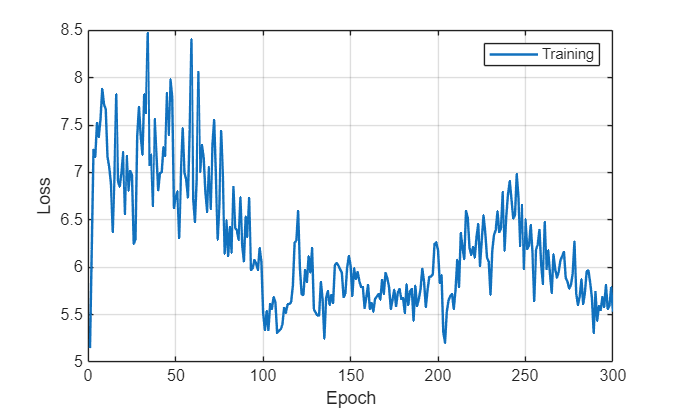

figure 
plot(dann_load.train_domain_loss, 'LineWidth', 1.5);
xlabel('Epoch');
ylabel('Loss');
% title('Domain Discrimination Loss (BCE Loss)');
legend('Training')
grid on;

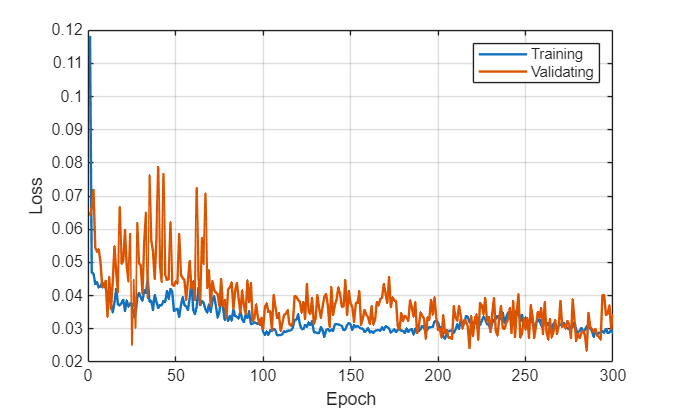


figure 
plot(dann_load.train_loss, 'LineWidth', 1.5);
hold on
plot(dann_load.val_loss, 'LineWidth', 1.5);
xlabel('Epoch');
ylabel('Loss');
% title('Domain Discrimination Loss (BCE Loss)');
legend('Training', 'Validating')
grid on;

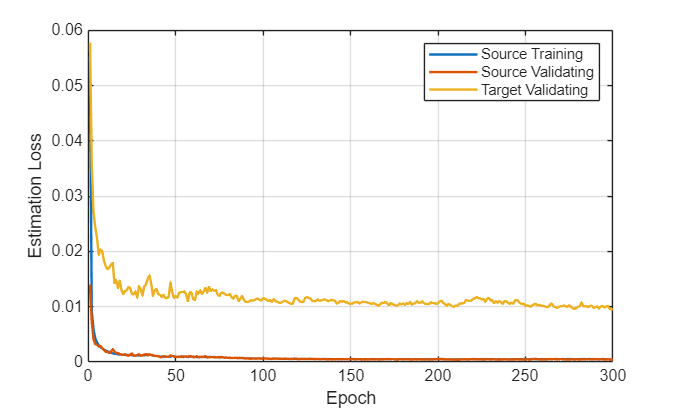


figure 
plot(dann_load.train_est_loss, 'LineWidth', 1.5);
hold on
plot(dann_load.val_est_loss_source, 'LineWidth', 1.5);
plot(dann_load.val_est_loss_target, 'LineWidth', 1.5);
xlabel('Epoch');
ylabel('Estimation Loss');
% title('Estimation Loss');
legend('Source Training', 'Source Validating', 'Target Validating')
grid on;

dann_load.train_est_loss(end)

ans = 4.8226e-04

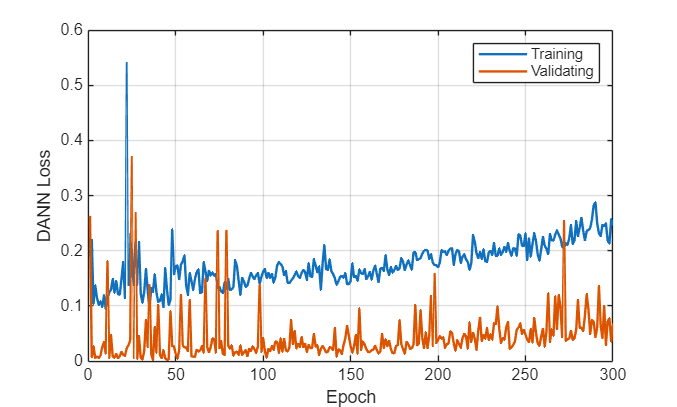

figure 
plot(dann_load.train_disc_loss, 'LineWidth', 1.5);
hold on
plot(dann_load.val_domain_loss, 'LineWidth', 1.5);
xlabel('Epoch');
ylabel('DANN Loss');
% title('Domain Discrimination Loss (BCE Loss)');
legend('Training', 'Validating')
grid on;

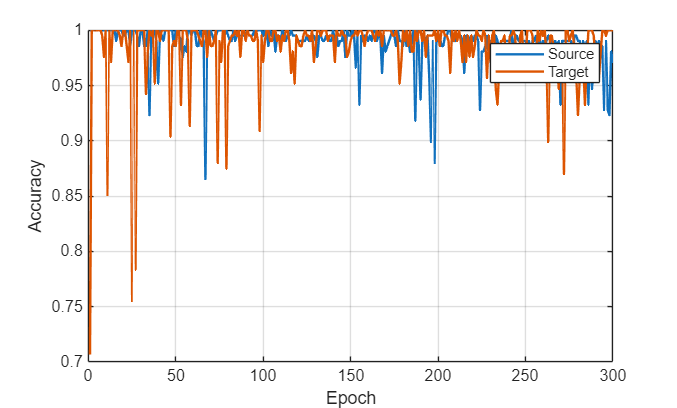

figure 
plot(dann_load.source_acc, 'LineWidth', 1.5);
hold on
plot(dann_load.target_acc, 'LineWidth', 1.5);
xlabel('Epoch');
ylabel('Accuracy');
% title('Domain Discrimination Accuracy);
legend('Source', 'Target')
grid on;